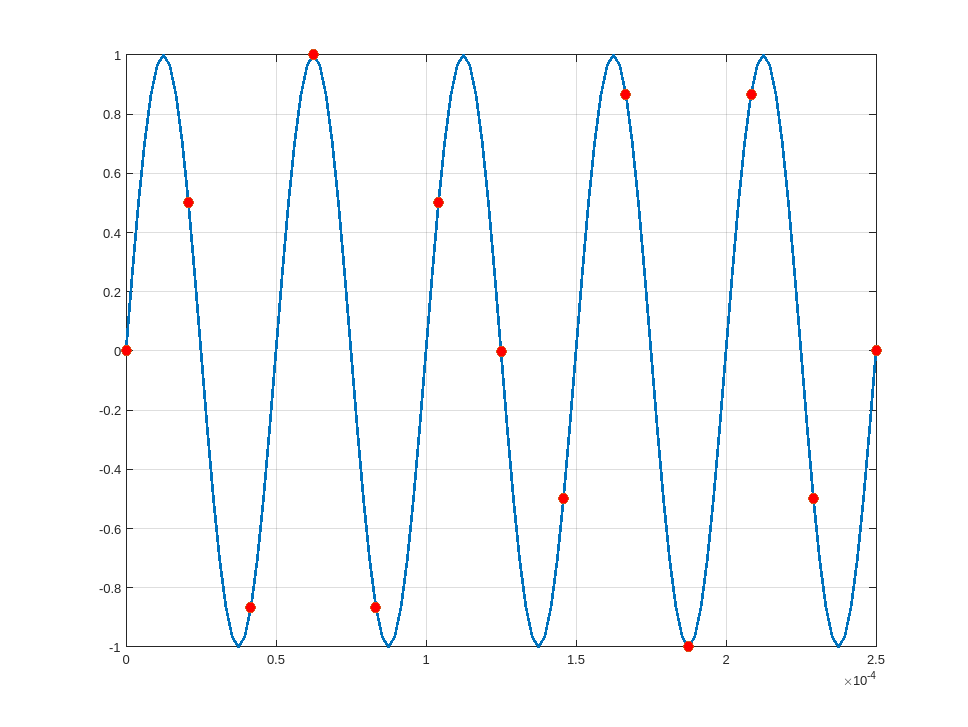

clc
clear
close all
fs = 48e3;
%fs = 2000;
t = 0:1/fs:1;
tIdeal = 0:1/(fs*10):1;
idealSig = sin(2*pi*tIdeal*20e3);
inputSig = sin(2*pi*t*20e3);

plot(tIdeal,idealSig, 'LineWidth', 2)
hold on
plot(t,inputSig, 'o', 'MarkerSize', 8, 'MarkerFaceColor', 'r')
hold on

delay = 0.25;               % Fractional delay amount
filterLength = 11;          % Number of FIR filter taps (should be odd)
centreTap = filterLength / 2;  % Position of centre FIR tap
%outputSig = length(inputSig)+filterLength
for t = 1:length(inputSig)
    % Apply FIR filter
    for tap = 1:filterLength       
        x = tap - delay;
        sinc = sin(pi * (x-centreTap)) / (pi * (x-centreTap));
        window = 0.54 - 0.46 * cos(2.0 * pi * (x+0.5) / filterLength);
        tapWeight = window * sinc;
        filterSum(tap) = tapWeight * inputSig(t);
        %fprintf('%3d % f % f % f\n', t, sinc, window, tapWeight);
    end
    outputSig(t) = sum(filterSum);
end

plot(t, outputSig, 'o', 'MarkerSize', 8, 'MarkerFaceColor', 'g')
xlim([0 5/20e3])
grid
hold off